Test wether there is no pressure

%% COmmon variables
clear all;
N = 200; % Number of harmonics
IDX = 18; % Which harmonics to test
M = 100; % Number of steps
dt = 1e-4;
initial_deformation = zeros(1, N);
initial_velocities  = ones(1, N);

f = @(n)  sqrt(n .* (n+2) .* (n-1) / 1);
omegas_frequencies = f(1:N)';
PROBLEM_CONSTANTS = struct("omegas_frequencies", omegas_frequencies);

g = @(t, idx) initial_deformation(idx) * cos(f(idx) * t) + initial_velocities(idx)/(f(idx)+1e-30) * sin(f(idx) * t);

initial_condition = struct("dt", dt, "nb_harmonics", N, ...
    "deformation_velocities", initial_velocities, "deformation_amplitudes", initial_deformation);
initial_condition_2 = initial_condition;
for idx = 1:N
    initial_condition_2.deformation_amplitudes(idx) = g(-dt, idx);
    initial_condition_2.deformation_velocities(idx) = (g(0, idx) - g(-2*dt/1000, idx))/(2*dt/1000);
end

previous_conditions = {initial_condition_2 initial_condition};


Testing ODE solver with adaptive time steps and no pressure

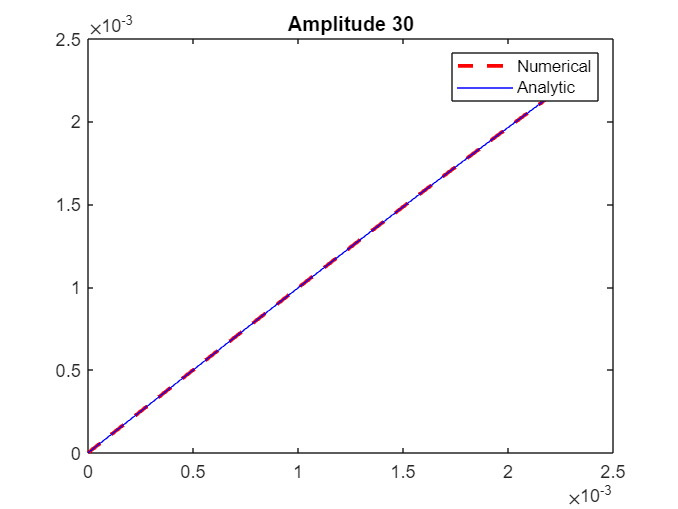

conditions = cell(M, 1); conditions{1} = initial_condition;
my_previous_conditions = previous_conditions;
t = zeros(1, M);
for ii = 2:M
    Dt = dt* (1 + rand()/3);
    t(ii) = t(ii-1) + Dt;
    [def, vel] = solve_ODE_unkown(nan, zeros(1, N), Dt, my_previous_conditions, PROBLEM_CONSTANTS);
    
    new_conditions = struct("dt", Dt, "nb_harmonics", N, ...
        "deformation_velocities", vel, "deformation_amplitudes", def);
    
    my_previous_conditions = {my_previous_conditions{end} new_conditions};
    conditions{ii} = new_conditions;
end

%t = linspace(0, dt*M, M);

defs = zeros(1, M);
real = zeros(1, M);
for ii = 1:M
    defs(ii) = conditions{ii}.deformation_amplitudes(IDX);
    real(ii) = g(t(ii), IDX);
end

clf; figure(3);
plot(t, defs, 'r--', 'LineWidth', 2);
hold on;
plot(t, real, 'b');
legend(["Numerical" "Analytic"]);
title(sprintf("Amplitude %d", IDX));

fprintf("The error is %.3g \n", norm(defs-real));

The error is 4.01e-08 


## Test that solve_ODE is an idempotent operator.



A = (rand(1, N)-1/2)/10; A(1) = 0; Deltat = dt * (0.5 + rand()/2);
[B, C] = solve_ODE_unkown(nan, A, Deltat, previous_conditions, PROBLEM_CONSTANTS);
D = solve_ODE_unkown(B, nan, Deltat, previous_conditions, PROBLEM_CONSTANTS);

E = (rand(1, N)-1/2)/10; E(1) = 0;
F = solve_ODE_unkown(E, nan, dt, previous_conditions, PROBLEM_CONSTANTS);
G = solve_ODE_unkown(nan, F, dt, previous_conditions, PROBLEM_CONSTANTS);

fprintf("La norma 2 de las presiones     es %.3g \n", norm(A-D));

La norma 2 de las presiones     es 1.1e-11 



fprintf("La norma 2 de las deformaciones es %.3g \n", norm(E-G));

La norma 2 de las deformaciones es 3.12e-17 


Symbolic pressure testing.

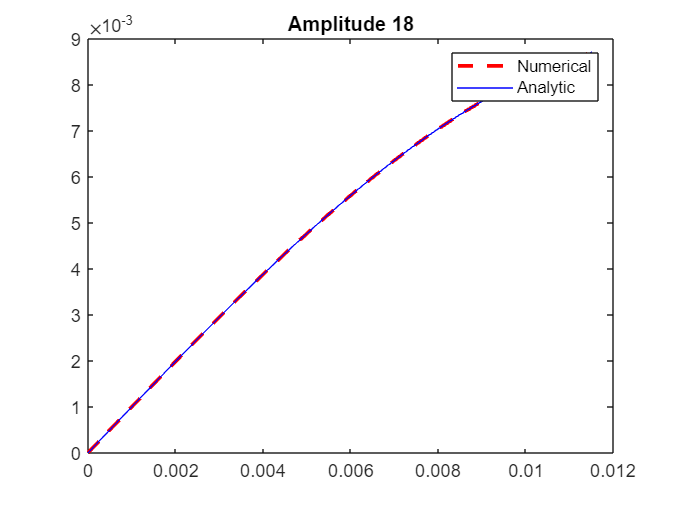

syms Bl(t) Al(t);
Bl(t) = 300*t;
ode = diff(Al, t, 2) == -IDX * Bl - omegas_frequencies(IDX)^2 * Al;
cond = Al(0) == previous_conditions{end}.deformation_amplitudes(IDX);
DAl = diff(Al, t);
cond2= DAl(0) == previous_conditions{end}.deformation_velocities(IDX);
ySol(t) = simplify(dsolve(ode, cond, cond2));
f = matlabFunction(ySol);


conditions = cell(M, 1); conditions{1} = initial_condition;
my_previous_conditions2 = previous_conditions;
t = zeros(1, M);
Bl = matlabFunction(Bl);
for ii = 2:M
    Dt = dt* (1 + rand()/3);
    t(ii) = t(ii-1) + Dt;
    pressures = Bl(t(ii)) * ones(1, N);
    [def, vel] = solve_ODE_unkown(nan, pressures, Dt, my_previous_conditions2, PROBLEM_CONSTANTS);
    
    new_conditions = struct("dt", Dt, "nb_harmonics", N, ...
        "deformation_velocities", vel, "deformation_amplitudes", def);
    
    my_previous_conditions2 = {my_previous_conditions2{end} new_conditions};
    conditions{ii} = new_conditions;
end

%t = linspace(0, dt*M, M);

defs = zeros(1, M);
real = zeros(1, M);
for ii = 1:M
    defs(ii) = conditions{ii}.deformation_amplitudes(IDX);
    real(ii) = f(t(ii));
end

clf; figure(1);
plot(t, defs, 'r--', 'LineWidth', 2);
hold on;
plot(t, real, 'b');
legend(["Numerical" "Analytic"]);
title(sprintf("Amplitude %d", IDX));

fprintf("The error is %.3g \n", norm(defs-real));

The error is 5.08e-06 
